%% delete the road with missing value
clc;
clear;
close all;
load .\data\tensor.mat;
% permute to time day road
tensortimedayroad= permute(tensor,[3 2 1]);
% road1=tensortimedayroad(:,:,1);
% road1totime=reshape(road1,size(road1,1)*size(road1,2),1);
% reshape to time road
tensortotime=reshape(tensortimedayroad,size(tensortimedayroad,1)*size(tensortimedayroad,2),size(tensortimedayroad,3),1);
% [zerorow,zerocol]=find(~tensortotime);
% missing value
missvalueindice = tensortotime==0;
% number of missing values for each road
missvalueroad = sum(missvalueindice);
% road with missing value
roadindicewithmissvalue = find(missvalueroad~=0);
% from 1 to 214 road
roadindice=[1:size(tensortotime,2)];
% road without missing value
roadindicewithoutmissvalue=setdiff(roadindice,roadindicewithmissvalue);
% choose the road without missing value
tensortotimewithoutmissvalue=tensortotime(:,roadindicewithoutmissvalue);
% plot(tensortotimewithoutmisscalue)
disp('Roads with missing value are')

Roads with missing value are


disp(roadindicewithmissvalue)

     3    34    48    55   123   146   147   166



disp('Roads without missing value are')

Roads without missing value are


disp(roadindicewithoutmissvalue)

  列 1 至 17

     1     2     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18

  列 18 至 34

    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    35    36

  列 35 至 51

    37    38    39    40    41    42    43    44    45    46    47    49    50    51    52    53    54

  列 52 至 68

    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72

  列 69 至 85

    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89

  列 86 至 102

    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106

  列 103 至 119

   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   124

  列 120 至 136

   125   126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141

  列 137 至 153

   142   143   144   145   148   149   150   

% compute the mean hour value
% one road example
% road1=tensortotimewithoutmisscalue(:,1);
% road1hour=reshape(road1,6,[]); % 10 minte
% road1hourmean=mean(road1hour)';
% reshape to hour road
roadminte=reshape(tensortotimewithoutmissvalue,6,size(tensortotimewithoutmissvalue,1)/6,[]);
roadhour=mean(roadminte,1);
roadhour= permute(roadhour,[2 3 1]);
% plot(roadhour)

% k-means clustering with dtw distance
tic
roadhourtrans = roadhour';
roadhourtransmean=mean(roadhourtrans,2);
roadhourtransmeanrep=repmat(roadhourtransmean,1,1464);
roadhourtranssubtraction=roadhourtrans-roadhourtransmeanrep;
% k-medoids Clustering
rng(1) % For reproducibility
[idx,c,sumd,d] = kmedoids(roadhourtranssubtraction,4,'Distance','cityblock','Replicates',3,'Options',statset('Display','iter')); % ,'Distance',@dtwf

   rep	    iter	         sum
     1	       1	      959327
     1	       2	      957503
     1	       3	      957503
     2	       1	      954280
     2	       2	      953883
     2	       3	      953883
     3	       1	      961556
     3	       2	      957503
     3	       3	      957503
距离的最佳总和 = 953883


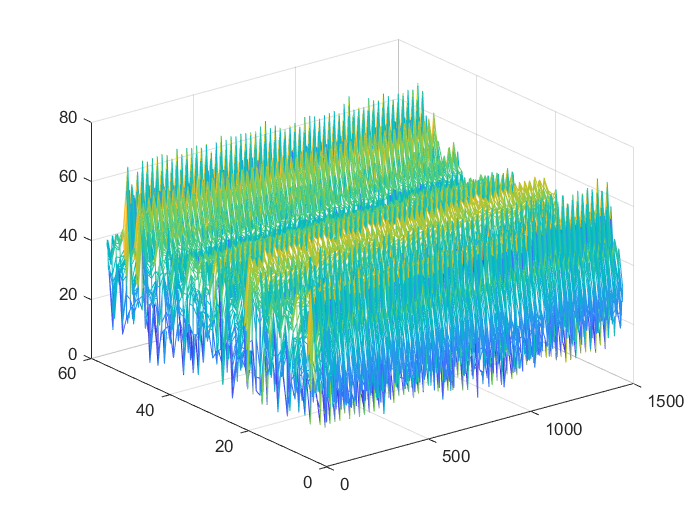

% cluster indices
cluster1=find(idx==1);
cluster2=find(idx==2);
cluster3=find(idx==3);
cluster4=find(idx==4);
% plot every cluster
figure
mesh(roadhourtrans(cluster1,:))

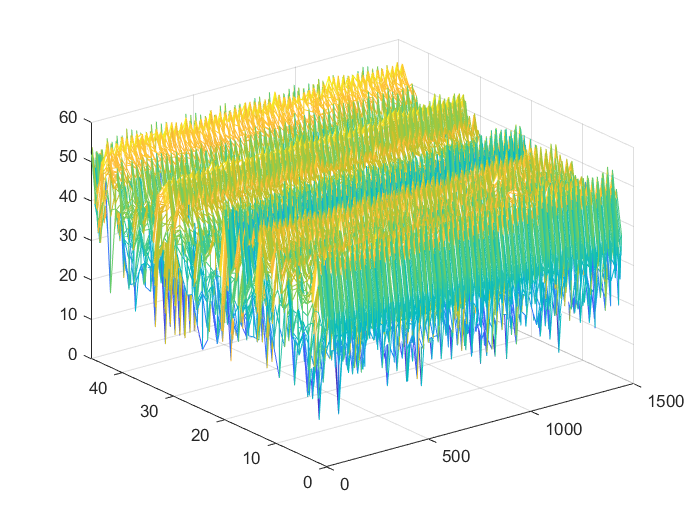

figure
mesh(roadhourtrans(cluster2,:))

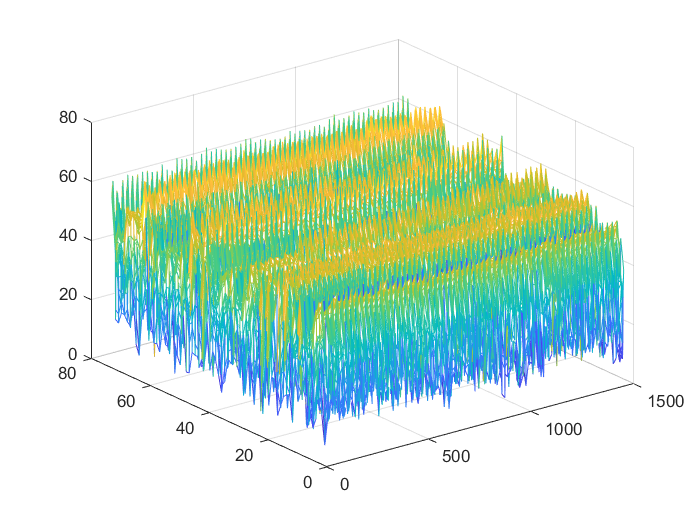

figure
mesh(roadhourtrans(cluster3,:))

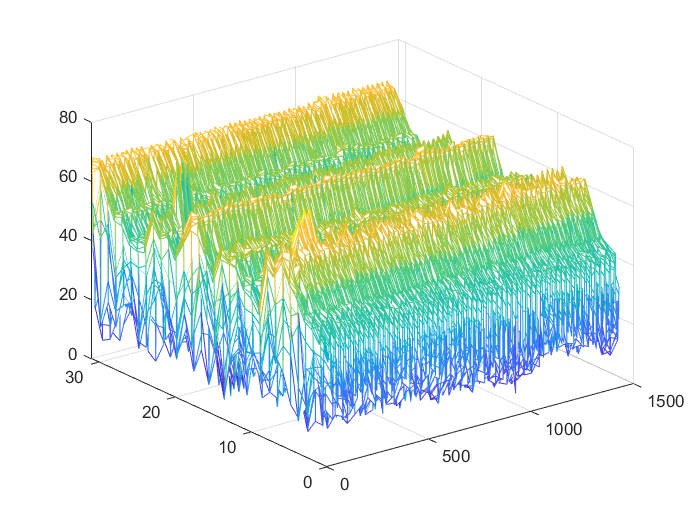

figure
mesh(roadhourtrans(cluster4,:))

% random sampling road1
cluster1indice=randperm(length(cluster1),1);
% road indice in all 206 road
road1sample=cluster1(cluster1indice);
% road indice in all 214 road
road1indice=roadindicewithoutmissvalue(road1sample);
% random sampling road2
cluster2indice=randperm(length(cluster2),1);
% road indice in all 206 road
road2sample=cluster2(cluster2indice);
% road indice in all 214 road
road2indice=roadindicewithoutmissvalue(road2sample);
% random sampling road3
cluster3indice=randperm(length(cluster3),1);
% road indice in all 206 road
road3sample=cluster3(cluster3indice);
% road indice in all 214 road
road3indice=roadindicewithoutmissvalue(road3sample);
% random sampling road4
cluster4indice=randperm(length(cluster4),1);
% road indice in all 206 road
road4sample=cluster4(cluster4indice);
% road indice in all 214 road
road4indice=roadindicewithoutmissvalue(road4sample);
% road indice in all 206 road
roadsample=[road1sample;road2sample;road3sample;road4sample];
% road indice in all 214 road
roadindice=[road1indice;road2indice;road3indice;road4indice];
disp('The selected road indice is')

The selected road indice is


disp(roadindice)

    33
   187
     2
   143



save('.\data\roadhour.mat','roadhour','roadsample','roadindice')
% writematrix(roadhour(:,roadsample),'D:\workspace\R\NGFM\data\trafficdata.csv');
toc

历时 2.975186 秒。


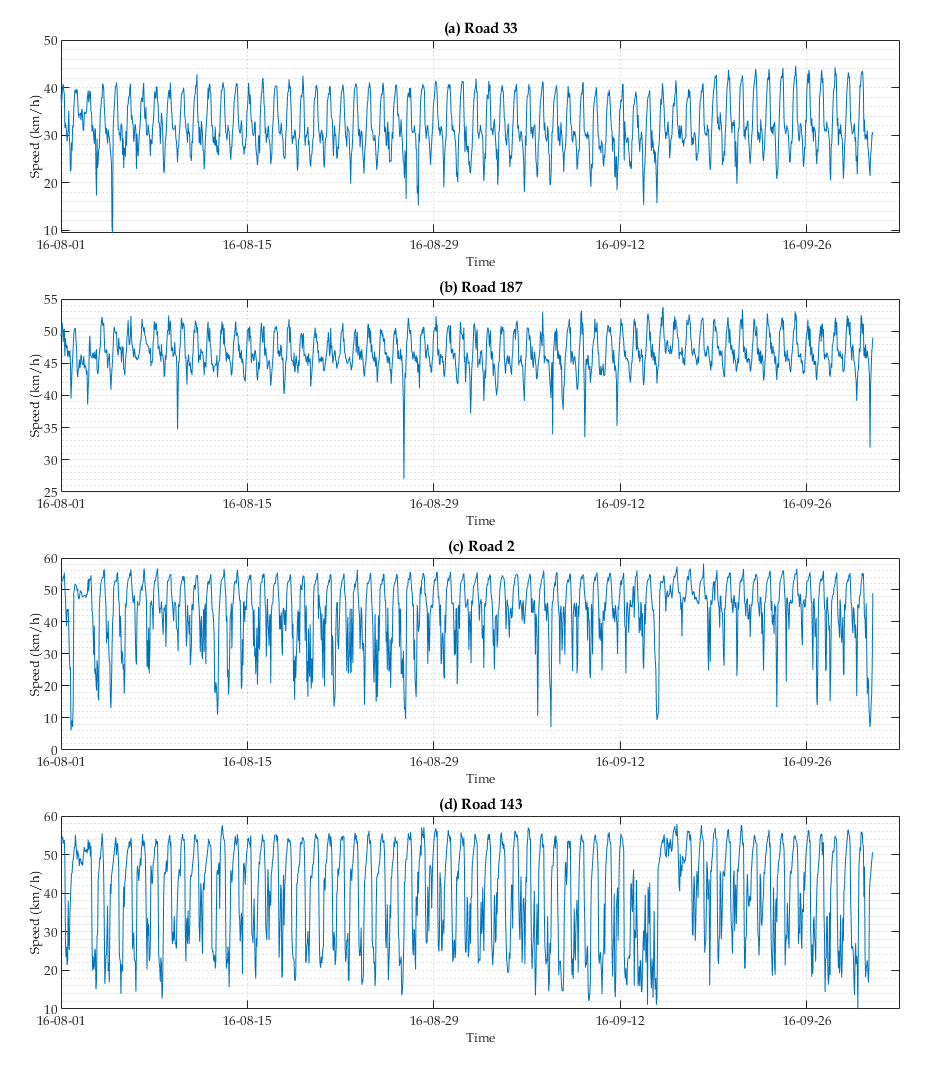

% plot
% figure setting
fig=figure('unit','centimeters','position',[5,0,20,40],'PaperPosition',[5, 0, 20,40],'PaperSize',[20,40]);
tiledlayout(4,1,'TileSpacing','Compact','Padding','Compact'); % new subfigure
tit={['(a) Road ',num2str(roadindice(1))],['(b) Road ',num2str(roadindice(2))],['(c) Road ',num2str(roadindice(3))],['(d) Road ',num2str(roadindice(4))]};
timestart=datetime(2016,08,01,0,0,0);
time=dateshift(timestart,'start','hour',0:1463); 
for i=1:4
    nexttile
    plot(time,roadhour(1:end,roadsample(i)),'LineStyle',"-",'LineWidth',0.3,'MarkerSize',4,'MarkerEdgeColor',[0.8500 0.3250 0.0980]);
    grid minor
    set(gca,'FontName','Book Antiqua','FontSize',8);
    xlabel('Time','FontSize',8);
    xtickformat('yy-MM-dd')
    ylabel({'Speed (km/h)'},'FontSize',8);
    title(tit(i),'FontWeight','bold','FontSize',8);
end
savefig(gcf,'.\figure\speed_data.fig');